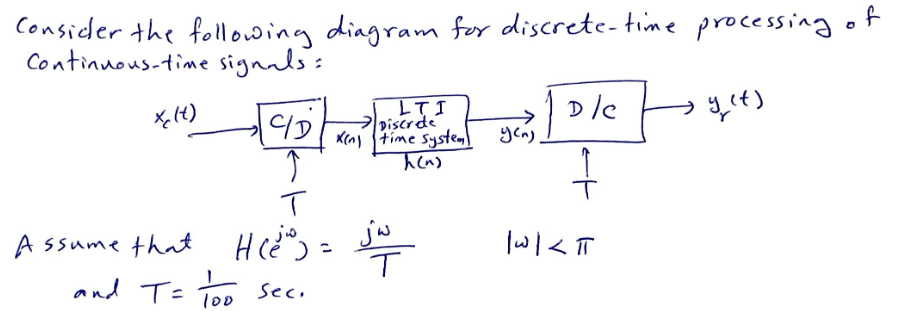

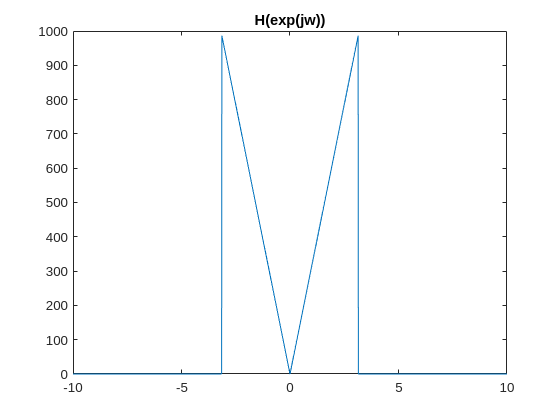

T = 1/100;
w = -10:T:10;

H = DSP_funcs.derivative(w);
plot(w, abs(H))
title("H(exp(jw))")

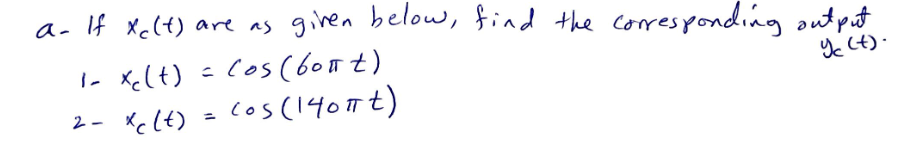

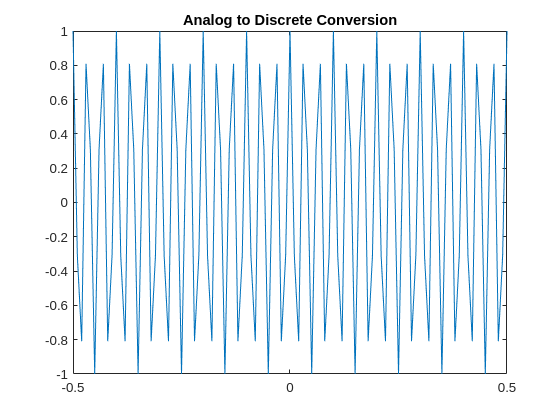

n = -10:T:10;

% Do analog to discrete conversion
x1 = cos(60*pi*n);
plot(n, x1)
xlim([-0.5,0.5])
title("Analog to Discrete Conversion")

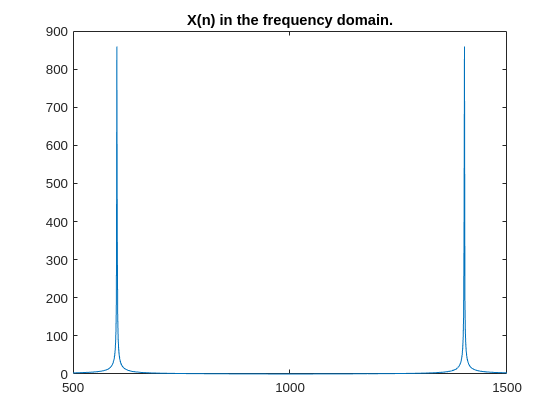


% convolve the input with H
X1 = fft(x1);
plot(abs(X1))
xlim([500,1500])
title("X(n) in the frequency domain.")

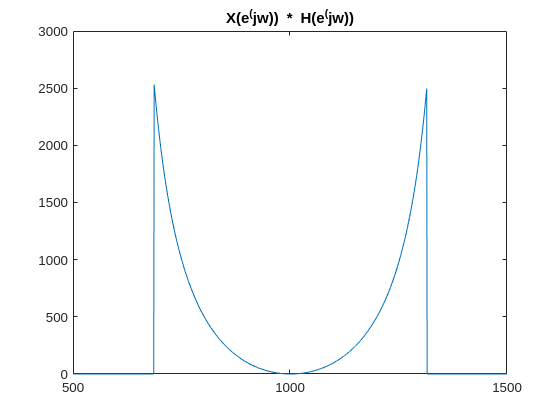

X1H = X1.*H;
plot(abs(X1H))
xlim([500, 1500])
title("X(e^(jw)) * H(e^(jw))")


% convert the convolved output back to the discrete time domain
y1n = ifft(X1H);
plot(n, y1n)

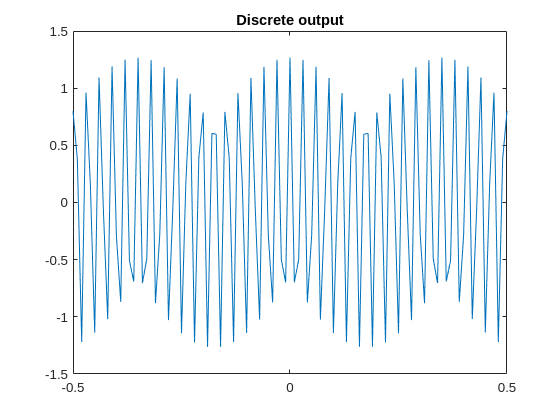

xlim([-0.5, 0.5])
title("Discrete output")


%convert from discrete domain to continuous domain

